## Identifying a model for a PMSM

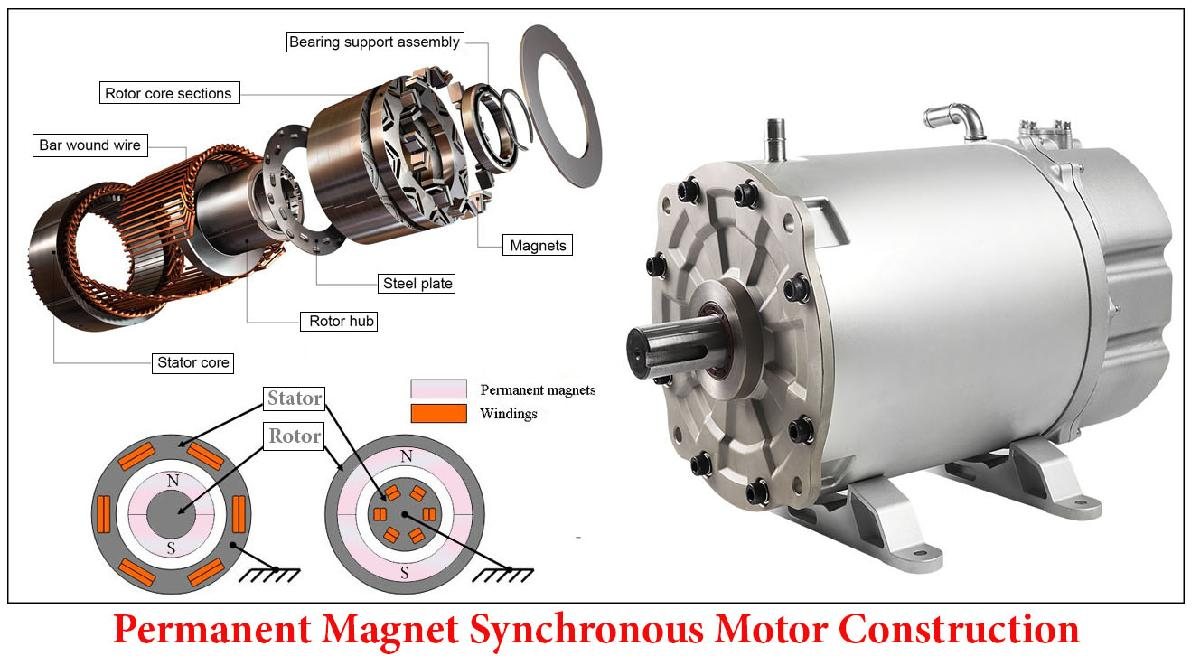

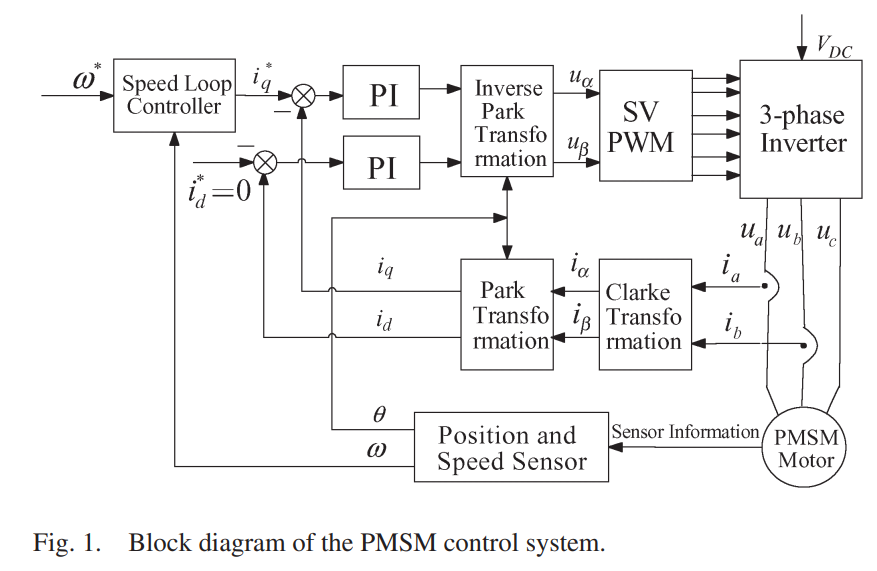

The motor is governed by the following system of differential equations

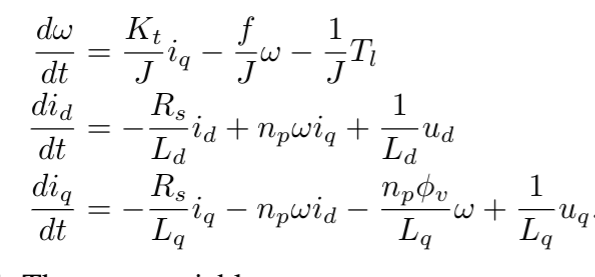

## Generate input data


h = 0.1;
uu = idinput(600, 'prbs', [0, 0.8]);

u1 = 100*uu(1:300);
u1v = 100*uu(301:600);
t = (0:299)'*h;
input1 = cat(2, t, u1);
input1v = cat(2, t, u1v);


## Load data

h = 0.1

h =    0.100000000000000


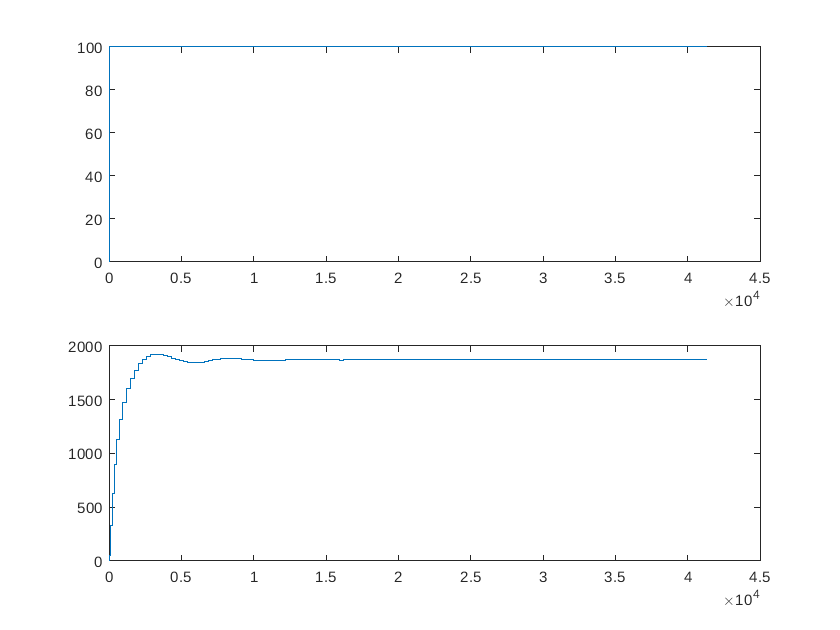

load pmsm_data.mat
figure()
subplot(211);
stairs(ustep)
subplot(212)
stairs(ystep)

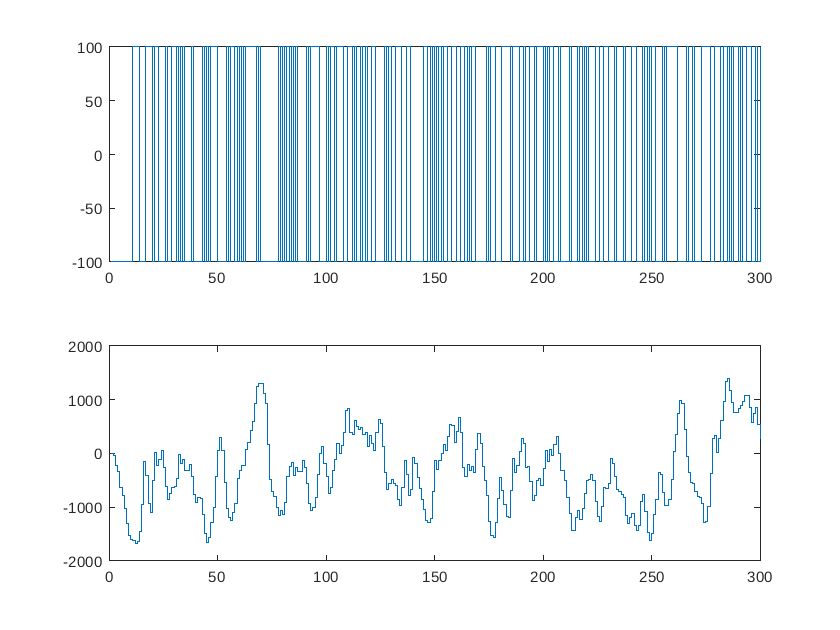


figure()
subplot(211);
stairs(uident)
subplot(212)
stairs(yident)

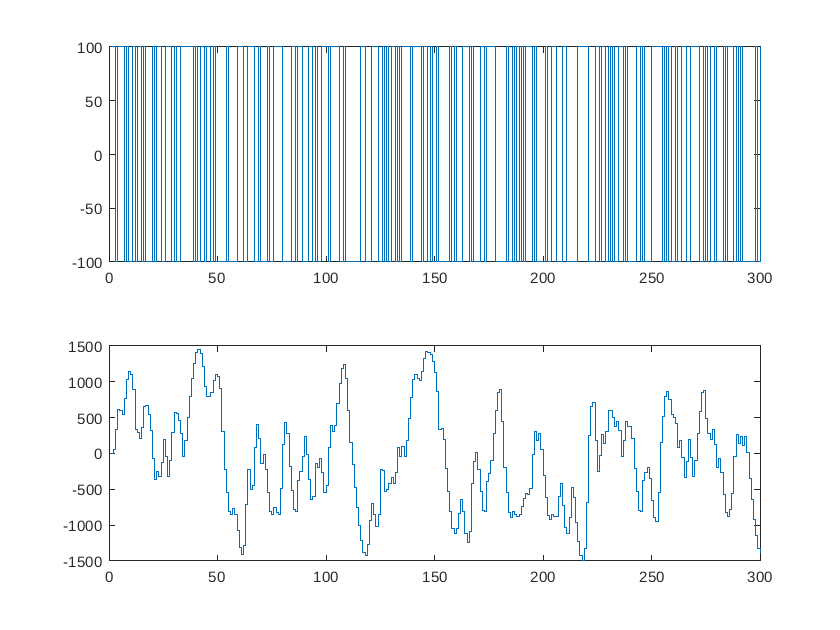


figure()
subplot(211);
stairs(uval)
subplot(212)
stairs(yval)

## Estimate models

iddta1 = iddata(yident,uident, h);
valdta1 = iddata(yval, uval, h);

% Second order model, one zero, two poles, one delay
% (b0 z + b1) / (z^2 + a1z + a2)
arx221 = arx(iddta1, [2, 2, 1])

arx221 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.407 z^-1 + 0.5011 z^-2              
                                                   
  B(z) = 0.1421 z^-1 + 1.518 z^-2                  
                                                   
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=1
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 74.11% (prediction focus)
FPE: 3.292e+04, MSE: 3.163e+04                   



% Second order model, one zero, two poles, two delays
% (b0 z + b1) /(z*(z^2 + a1z + a2))
arx222 = arx(iddta1, [2, 2, 2])

arx222 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.206 z^-1 + 0.3122 z^-2              
                                                   
  B(z) = 1.566 z^-2 + 0.9568 z^-3                  
                                                   
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=2
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 76.67% (prediction focus)
FPE: 2.673e+04, MSE: 2.569e+04                   



% fourth order model, three zeros, four poles, one delay
% (b0 z^3 + b1z^2 + b2z + b3) / (z^4 + a1z^3 + a2z^2 + a3z + a4)
arx441 = arx(iddta1, [4, 4, 1])

arx441 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)               
  A(z) = 1 - 1.204 z^-1 + 0.4838 z^-2 - 0.1834 z^-3 + 0.01277 z^-4
                                                                  
  B(z) = 0.1802 z^-1 + 1.567 z^-2 + 0.994 z^-3 + 0.4723 z^-4      
                                                                  
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 77.62% (prediction focus)
FPE: 2.562e+04, MSE: 2.365e+04                   



% sixth order model, five zeros, six poles, one delay
arx661 = arx(iddta1, [6, 6, 1])

arx661 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                            
  A(z) = 1 - 1.182 z^-1 + 0.5107 z^-2 - 0.2165 z^-3 + 0.02146 z^-4 + 0.0185 z^-5 - 0.03944 z^-6
                                                                                               
  B(z) = 0.169 z^-1 + 1.588 z^-2 + 1.062 z^-3 + 0.5992 z^-4 + 0.2013 z^-5 + 0.0355 z^-6        
                                                                                               
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=6   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 77.84% (prediction focus)
FPE: 2.613e+04, MSE: 2.317e+04                   



% eigth order model, seven zeros, eight poles, one delay
arx881 = arx(iddta1, [8, 8, 1])

arx881 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                            
  A(z) = 1 - 1.178 z^-1 + 0.5033 z^-2 - 0.2262 z^-3 + 0.01643 z^-4 - 0.03382 z^-5 + 0.05625 z^-6 - 0.04486 z^-7 + 0.007672 z^-8
                                                                                                                               
  B(z) = 0.1708 z^-1 + 1.587 z^-2 + 1.062 z^-3 + 0.6003 z^-4 + 0.174 z^-5 - 0.0277 z^-6 - 0.1919 z^-7 - 0.1052 z^-8            
                                                                                                                               
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   na=8   nb=8   nk=1
   Number of free coefficients: 16
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 77.94% (prediction focu


% 12th order model, 
arx12121 = arx(iddta1, [12, 12, 1])

arx12121 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                                                             
                                                                                                                                                                                
  A(z) = 1 - 1.174 z^-1 + 0.4978 z^-2 - 0.2133 z^-3 + 0.005182 z^-4 - 0.03485 z^-5 + 0.07451 z^-6 - 0.08282 z^-7 + 0.07214 z^-8 + 0.02261 z^-9 - 0.02007 z^-10 - 0.003902 z^-11 
                                                                                                                                                             - 0.03717 z^-12    
                                                                                                                                                                                
                                                                                                        

## Compare models

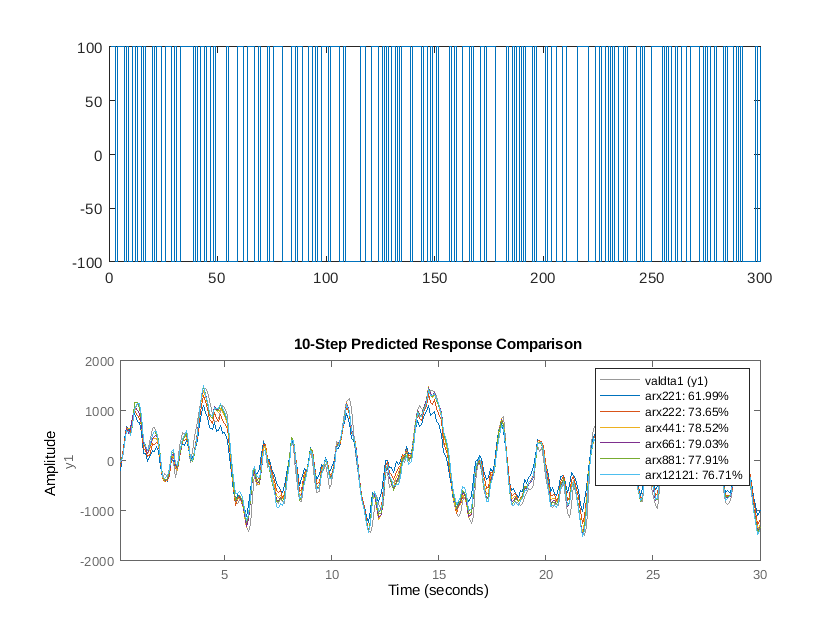

compare(valdta1, arx221, arx222, arx441, arx661, arx881, arx12121,10)

aic(arx221, arx222, arx441, arx661, arx881, arx12121)

Model quality according to the "nAIC" measure:
  10.401827723360649  10.193713908180623  10.151071230918093  10.170625255027034  10.201897661439702  10.239350595990024

